The process model defines the evolution of the state from time *k*−1 to time *k* as:


$$x_k ={\textrm{Fx}}_{k-1} +{\textrm{Bu}}_{k-1} +w_{k-1}$$


The process model is paired with the measurement model 


$$z_k ={\textrm{Hx}}_k +v_k$$


To the actual implementation of the the loop:

**Prediction:**


$${{\hat{x} }^- }_k ={{F\hat{x} }^+ }_{k-1} +{\textrm{Bu}}_{k-1}$$



$$P_k^- =FP_k^+ F^T +Q$$


**Update:**


$$\tilde{y} =z_k -H{{\hat{x} }^- }_k$$



$$K_k =P_k^- H^T {\left(R+HP_k^- H^T \right)}^{-1}$$



$${{\hat{x} }^+ }_k ={{\hat{x} }^- }_k +K_k \tilde{y}$$



$$P_k^- =\left(I-K_k H\right)P_k^-$$


We simply have to define $H$, $B$, $F$

**Example code**

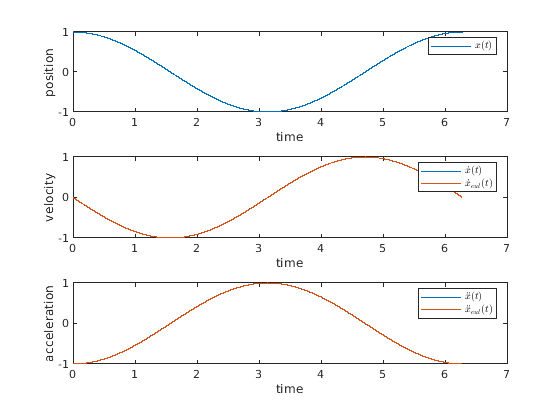

% generate some data:
clf; clc;
dt = 0.001;
t = 0:dt:2*pi;

% define x
x = cos(t);
figure(1)
subplot(3,1,1)
plot(t,x)
legend('$x(t)$','Interpreter','latex')
xlabel('time')
ylabel('position')

% define xdot
xdot = -sin(t);
% euler approx
xdot_eul = (x(2:end)-x(1:end-1))/(dt);

subplot(3,1,2)
plot(t,xdot)
hold on;
plot(t(2:end),xdot_eul)
legend('$\dot{x}(t)$','$\dot{x}_{eul}(t)$','Interpreter','latex')
xlabel('time')
ylabel('velocity')

% define xdot
xddot = -cos(t);
% euler approx
xddot_eul = (xdot_eul(2:end)-xdot_eul(1:end-1))/(dt);

subplot(3,1,3)
plot(t, xddot)
hold on;
plot(t(3:end), xddot_eul)
legend('$\ddot{x}(t)$','$\ddot{x}_{eul}(t)$','Interpreter','latex')
xlabel('time')
ylabel('acceleration')

**Implementing the kalman filter given above to estimate **$\dot{x}$** when it has some measurement noise**

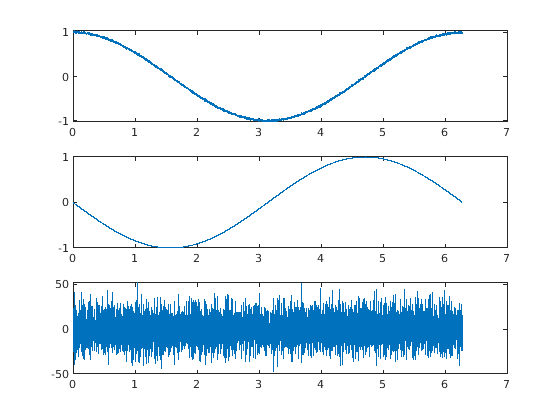

clc; clf; 

% generate some data:
clf; clc;
dt = 0.001;
t = 0:dt:2*pi;

% define x
x = cos(t) + 0.01*randn(size(t));

% define xdot
xdot = -sin(t);

% euler approx
xdot_eul = (x(2:end)-x(1:end-1))/(dt);

figure(2)
subplot(3,1,1)
plot(t,x)
subplot(3,1,2)
plot(t,xdot)
hold on;
subplot(3,1,3)
plot(t(2:end), xdot_eul)

**The implementation of the kalman filter given no **$u\left(t\right)$

$F=1$, $B=0$, $Q=\sigma {\;}_{\mathrm{model}}$, $P=1$, $H=1$, $R=\sigma {\;}_{\mathrm{mes}}$

clc;
F = [ 1 ]

F = 1

B = [ 0.001 ]

B = 1.0000e-03

Q = [ 0.001 * 0.001 ]

Q = 1.0000e-06

P = [ 0.001 ] % sart

P = 1.0000e-03

H = [ 1 ]

H = 1

R = [ 0.1 ]

R = 0.1000

u = -cos(t)

u =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9997   -0.9997   -0.9997   -0.9997   -0.9996   -0.9996   -0.9996   -0.9996   -0.9995   -0.9995   -0.9995   -0.9994   -0.9994   -0.9994   -0.9993   -0.9993   -0.9992   -0.9992   -0.9992   -0.9991   -0.9991   -0.9990   -0.9990   -0.9989   -0.9989   -0.9988   -0.9988



xdot_pre = zeros(1, length(xdot))

xdot_pre =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = zeros(1, length(xdot))

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


K = zeros(1, length(xdot))

K =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


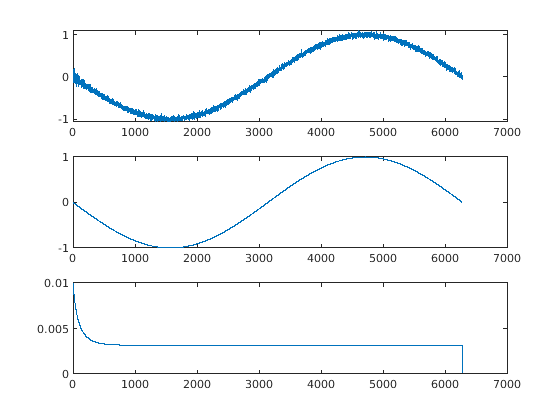


for i = 1:length(xdot)-1
    
    % Prediction 
    xdot_pre(i+1) = F * xdot_pre(i) + B * u(i+1);
    P = F*P*F' + Q;
    
    % Update
    y(i) = H*xdot_eul(i) - H*xdot_pre(i+1);
    K(i) = P*H'/(R+H*P*H');
    xdot_pre(i+1) = xdot_pre(i+1) + K(i)*y(i);
    P = (1 - K(i)*H)*P;
    
end
clf;
figure(3)
subplot(3,1,1)
plot(xdot_pre)
subplot(3,1,2)
plot(xdot)
subplot(3,1,3)
plot(K)

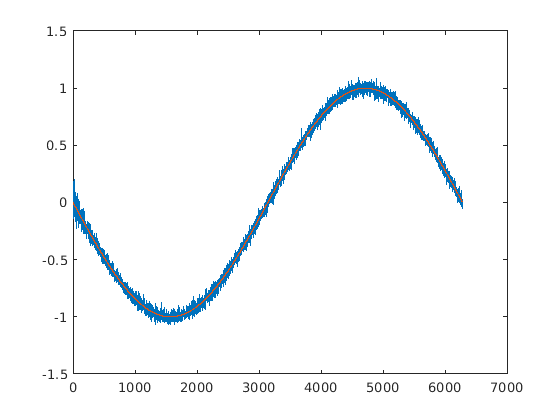

figure(4)
plot(xdot_pre)
hold on;
plot(xdot)
hold on;

%plot(xdot_eul)